clc
clear
Kt = 0.011;
Km = 327*10^-6;
m = 1.513;
Ixx = 0.0185;
Iyy = 0.0201;
Izz = 0.0286;
g = 9.82;
lroll = 0.175;
lpitch = 0.175;

A = [zeros(6,6)  [0 0 0 0 -g 0; 0 0 0 g 0 0 ; zeros(4,6)];
    eye(6) zeros(6,6)];
B = [zeros(4,2) [Kt/m -(lroll*Kt)/(Ixx) -(lpitch*Kt)/(Iyy) (Km)/(Izz); 
    Kt/m (lroll*Kt)/(Ixx) (lpitch*Kt)/(Iyy) (Km)/(Izz); 
    Kt/m (lroll*Kt)/(Ixx) -(lpitch*Kt)/(Iyy) -(Km)/(Izz); 
    Kt/m -(lroll*Kt)/(Ixx) (lpitch*Kt)/(Iyy) -(Km)/(Izz)] zeros(4,6)].';

C = [0 0 0 0 0 0 1 0 0 0 0 0 ;
     0 0 0 0 0 0 0 1 0 0 0 0 ;
     0 0 0 0 0 0 0 0 1 0 0 0 ;
     0 0 0 0 0 0 0 0 0 1 0 0 ;
     0 0 0 0 0 0 0 0 0 0 1 0 ;
     0 0 0 0 0 0 0 0 0 0 0 1 ;];
D = zeros(6,4);

s=tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


tfs = (C/(s*eye(12)-A))*B;
X_Omega = tfs(1,1);
phi_Omega = tfs(5,3);
x_phi = X_Omega/phi_Omega;
y_omega = tfs(2,2);
theta_omega = tfs(4,2);
y_theta = y_omega/theta_omega;

transfer_function = tfs(5,2)

transfer_function =
 
            0.09577
  ----------------------------
  s^2 + 3.657e-17 s - 5.62e-33
 
Continuous-time transfer function.
Model Properties


sim_time = 20;

reference_Input_Grader = 20;
stepRef = pi/180*reference_Input_Grader;
Saturation_Rad_pr_s = 1000;
Saturation = Saturation_Rad_pr_s;
% Kp = 32.4675
% Ki = 2.3117
% Kd = 10.8961
Kp = 100

Kp = 100

Ki = 20

Ki = 20

Kd = 20

Kd = 20


simData = sim('PID_Sim');
ref = simData.yout{3}.Values.Data;
uout = simData.yout{2}.Values.Data;
yout = simData.yout{1}.Values.Data;
uoutSat = simData.yout{4}.Values.Data;
tout = simData.tout;
omega_max = (max(uout)/0.175)/0.011;
omega_max_sat = (max(uoutSat)/0.175)/0.011;

S = stepinfo(yout, tout, stepRef)

S = struct with fields:
         RiseTime: 0.3164
    TransientTime: 4.3903
     SettlingTime: 4.3903
      SettlingMin: 0.2800
      SettlingMax: 0.5203
        Overshoot: 49.0445
       Undershoot: 0
             Peak: 0.5203
         PeakTime: 0.8548


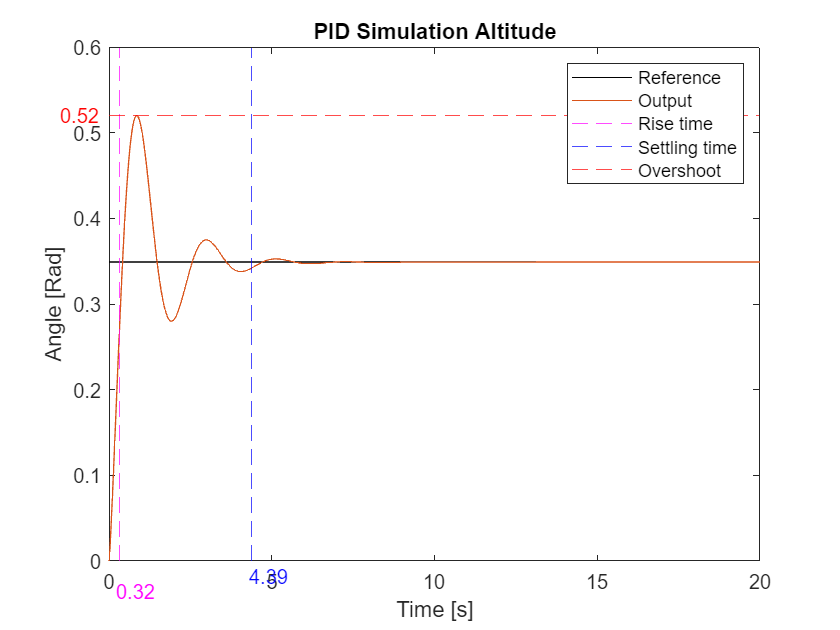

plot(tout,ref,'black',tout, yout)
title('PID Simulation Altitude')
xlabel('Time [s]');
ylabel('Angle [Rad]');
xline(S.RiseTime,'--',Color='[1,0,1]')
xline(S.SettlingTime,'--',Color='b')
yline(S.Peak,'--',Color='[1,0,0]')
text(-1.5, S.Peak, sprintf('%.2f', S.Peak),Color='[1,0,0]');
text(S.RiseTime-0.1, -0.035, sprintf('%.2f', S.RiseTime),Color='[1,0,1]');
text(S.SettlingTime-0.1, -0.017, sprintf('%.2f', S.SettlingTime),Color='b');
legend('Reference','Output','Rise time','Settling time','Overshoot')

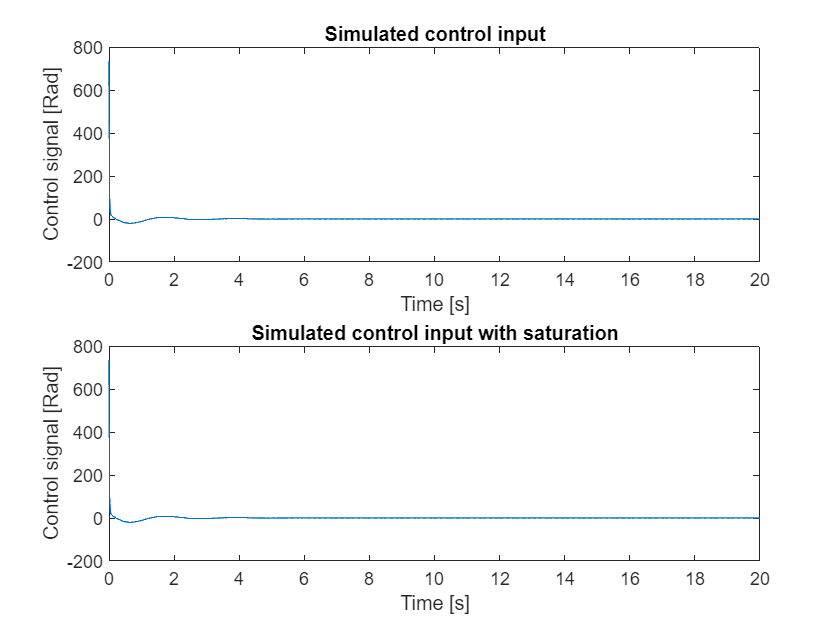



subplot(2,1,1)
plot(tout,uout)
title('Simulated control input')
ylabel('Control signal [Rad]')
xlabel('Time [s]')
subplot(2,1,2)
plot(tout,uoutSat)
title('Simulated control input with saturation')
ylabel('Control signal [Rad]')
xlabel('Time [s]')